# Sembolik Heaplamalar

Sembolik Matematik Araç Kutusu, sembolik matematik denklemlerini çözmek, çizmek ve işlemek için fonksiyonlar sağlar. MATLAB Live Editor kullanarak sembolik matematik kodunu oluşturabilir, çalıştırabilir ve paylaşabilirsiniz. Araç kutusu, matematik, doğrusal cebir, cebirsel ve adi diferansiyel denklemler, denklem sadeleştirmesi ve denklem manipülasyonu gibi ortak matematiksel alanlarda işlevler sağlar.

Sembolik Matematik Araç Kutusu türev, integral, sadeliştirme, dönüşüm ve denklem çözme işlemlerini analitik olarak yapmanıza olanak sağlar. SI ve ABD birim sistemlerini kullanarak boyutlu hesaplamalar ve dönüşümler yapabilirsiniz. Hesaplamalarınız, matematiksel dizgide görüntülenen sonuçlarla, analitik veya değişken hassasiyetli aritmetik kullanılarak yapılabilir.

**SEMBOLİK İFADELER ÜZERİNDE İŞLEMLER**

## sym ve syms nedir ?

**syms: **Herhangi bir değişkeni sembolik olarak tanımlamak için syms komutu kullanılır.

Örnek: x değişkenini sembolik olarak tanımlama

syms x;

MATLAB'deki değişkenler varsayılan olarak çift duyarlıdır. Sembolik Matematik Araç Kutusu, sayıları sym kullanarak tam sembolik biçimde ve vpa kullanarak değişken hassasiyetle ifade etmenize izin vererek bunu genişletir.

pi/6 + pi/4

ans = 1.3090

sym(pi/6) + sym(pi/4)

$$ans = \frac{5\,\pi }{12}$$

vpa(pi/6) + vpa(pi/4)

$$ans = 1.3089969389957471826927680763665$$

Sembolik değişkenler trigonometrik, logaritmik, üstel ve özel fonksiyonlar dahil matematiksel ifadelerde, fonksiyonlarda ve denklemlerde kullanılabilir. Sembolik ifadeler oluşturabilir ve üzerlerinde matematiksel hesaplamalar yapabilirsiniz.

syms x y 
log(x) + exp(y)

$$ans = {\mathrm{e}}^{y}+\log\left(x\right)$$

Parça fonksiyonlar da oluşturabilirsiniz.

y(x) = piecewise(x<0, -1, x>0, 1)

$$y(x) = \left\{ \begin{array}{cl} -1 & \text{ if }x<0\\ 1 & \text{ if }0<x \end{array}\right.$$

Fonksiyon oluşturup ve değer hesaplaması yapabilirsiniz.  `f` fonksiyonun $x = -5$ değerini bulun.

syms f(x)
f(x) = x^4-2*x^3+6*x^2-2*x+10

$$f(x) = x^{4}-2\,x^{3}+6\,x^{2}-2\,x+10$$

f(-5)

$$ans = 1045$$

Doğrular arasında kesişme noktasını solve kullanarak bulun. == operatörünü kullanarak doğruları eşitleyin.

syms x y1 y2
y1 = x+3; y2 = 3*x;
solve(y1 == y2)

$$ans = \frac{3}{2}$$

Make [assumptions](matlab:helpview([docroot '/symbolic/assume.html'])) on symbolic variables. There are 4 solutions to $x^4=1$, two real and two complex.  Assuming that x is real and $x > 0 $, there is only one solution.

syms x
solve(x^4 == 1)

$$ans = \left(\begin{array}{c} -1\\ 1\\ -\mathrm{i}\\ \mathrm{i} \end{array}\right)$$

assume(x,'real')
assumeAlso( x > 0)
assumptions(x)

$$ans = \left(\begin{array}{cc} x\in \mathbb{R} & 0<x \end{array}\right)$$

solve(x^4 == 1)

$$ans = 1$$

assume(x,'clear')

Geçerli değişken adları olmayan ve bir sayı tanımlamayan karakter vektörlerinin desteği, gelecek sürümlerde kaldırılacaktır. Sembolik ifadeler oluşturmak için önce sembolik değişkenler oluşturun ve ardından üzerlerindeki işlemleri kullanın. ** Örneğin **`sym('x + 1') yerine syms x; x + 1`** kullanınız. **`sym('exp(pi)') yerine exp(sym(pi))`** ve  **`f(var1,...varN) = sym('f(var1,...varN)') yerine` `syms f(var1,...varN) kullanın.`

x = sym('x')

$$x = x$$

syms x

syms daha önce tanımlanmış olsa bile bir sembolü tekrar tanımlar, içeriğini siler. 

syms a b x
2*a+5*b-7*a+x

$$ans = 5\,b-5\,a+x$$

symsvar bir sembolik ifadenin içindeki sembolik değişkenleri bulur.

symvar(55+a*x^2+b*x^3+a*x)

$$ans = \left(\begin{array}{ccc} a & b & x \end{array}\right)$$

subs : yerine yazmak.. 

`subs(s,old,new)`

`subs(s,new)`

`subs(s)`

syms a b
symvar(a+b)

$$ans = \left(\begin{array}{cc} a & b \end{array}\right)$$

symvar(b+a)

$$ans = \left(\begin{array}{cc} a & b \end{array}\right)$$

subs(a + b, a,4)

$$ans = a+4$$

simple fonksiyonu yeni Matlab sürümlerinde kaldırılmıştır. Bunun yerine simplify kullanılması gerekmektedir.

syms t;
(cos(t)^2+sin(t)^2)

$$ans = {\cos\left(t\right)}^{2}+{\sin\left(t\right)}^{2}$$

simplify(cos(t)^2+sin(t)^2)

$$ans = 1$$

expand

expand((t+1)^3)

$$ans = t^{3}+3\,t^{2}+3\,t+1$$

expand(cos(a+b))

$$ans = \cos\left(a\right)\,\cos\left(b\right)-\sin\left(a\right)\,\sin\left(b\right)$$

expand(sin(a+b))

$$ans = \cos\left(a\right)\,\sin\left(b\right)+\cos\left(b\right)\,\sin\left(a\right)$$

collect

syms t x
collect((2*t^3-x^3+5*x+t^2+4*t+2*t^3+3*x*t^2+8*t)^3,x)

$$ans = \begin{array}{l} -x^{9}+\left(9\,t^{2}+15\right)\,x^{7}+\left(12\,t^{3}+3\,t^{2}+36\,t\right)\,x^{6}+\left(-\sigma_{2}\,\sigma_{4}-{\sigma_{2}}^{2}\right)\,x^{5}+\left(-\sigma_{2}\,\sigma_{1}\,2-\sigma_{4}\,\sigma_{1}-\sigma_{2}\,\sigma_{3}\right)\,x^{4}+\left(-\sigma_{1}\,\sigma_{3}-{\sigma_{1}}^{2}+{\sigma_{2}}^{3}\right)\,x^{3}+\left({\sigma_{2}}^{2}\,\sigma_{1}\,3\right)\,x^{2}+\left(\sigma_{2}\,{\sigma_{1}}^{2}\,3\right)\,x+{\sigma_{1}}^{3}\\ \mathrm{where}\\ \sigma_{1}=4\,t^{3}+t^{2}+12\,t\\ \sigma_{2}=3\,t^{2}+5\\ \sigma_{3}=8\,t^{3}+2\,t^{2}+24\,t\\ \sigma_{4}=6\,t^{2}+10 \end{array}$$

factor

factor(t^3+6*t^2+12*t+8)

$$ans = \left(\begin{array}{ccc} t+2 & t+2 & t+2 \end{array}\right)$$

numden

syms s
G=s+4+2/(s+4)+3/(s+2)

$$G = s+\frac{3}{s+2}+\frac{2}{s+4}+4$$

[pay,payda] = numden(G)

$$pay = s^{3}+10\,s^{2}+37\,s+48$$

$$payda = \left(s+2\right)\,\left(s+4\right)$$

sym2poly(4*s^3-2*s^2+5*s-16)

ans =      4    -2     5   -16


poly2sym([ 1 4 -7 -10],t)

$$ans = t^{3}+4\,t^{2}-7\,t-10$$

pretty(ans)

 3      2
t  + 4 t  - 7 t - 10



Sembolik ifadelerin grafiklerinin çizdirilmesi

syms s
E=s^3-14*s^2+65*s-100;

ezplot  ezplot is not recommended. Use fplot instead.

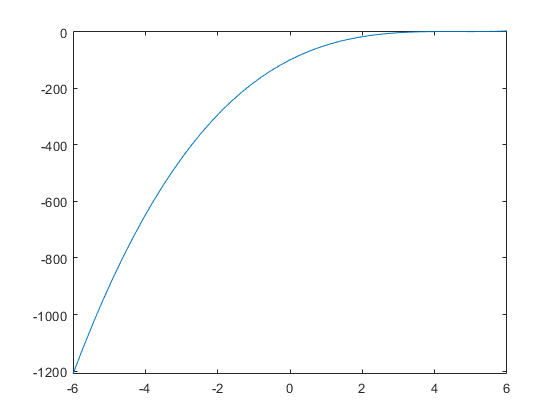

fplot(E,[-6,6])

solve

syms x y
denk1 = x^2==5*y+3;
denk2 = x^2-4*y+3==0;
[x,y] = solve(denk1,denk2)

$$x = \left(\begin{array}{c} -\frac{\sqrt{3}\,\mathrm{i}}{3}\\ \frac{\sqrt{3}\,\mathrm{i}}{3} \end{array}\right)$$

$$y = \left(\begin{array}{c} \frac{2}{3}\\ \frac{2}{3} \end{array}\right)$$

*

 : Differential equations and systems solver

cos , sin

Koordinat Sistemleri

Kutupal Koordinat 

Polar

Örnek : 

syms x y z 
d1 = 22*x-33*y+44*z==55;
d2 = 3*y+4*z+5*x==38;
d3 = -18*z-28*x-38*y==-150;
[xs,ys,zs] = solve(d1,d2,d3)

$$xs = \frac{623}{27}$$

$$ys = -\frac{163}{27}$$

$$zs = -\frac{400}{27}$$

sayisal = vpa([xs ys zs] ,30)

$$sayisal = \left(\begin{array}{ccc} 23.0740740740740740740740740741 & -6.03703703703703703703703703704 & -14.8148148148148148148148148148 \end{array}\right)$$


xss = vpa(xs,30)

$$xss = 23.0740740740740740740740740741$$

xssd = double(xss)

xssd =   23.074069999999999
